# Problem 7

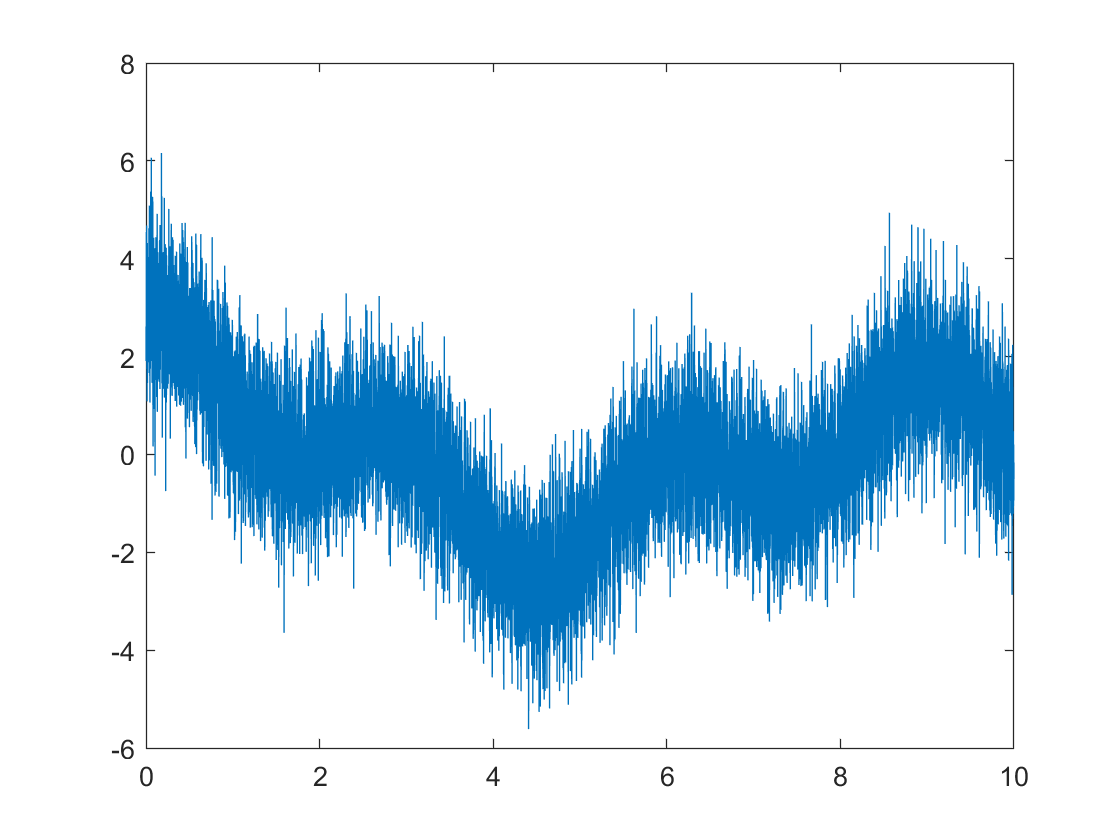

% generate signals
T = 0.001;
Fs = 1/T;
n = 0:T:10-T;
f = (Fs*(0:length(n)-1)/length(n));

x1 = cos(pi*n/6);
x2 = cos(pi*n/4);
x3 = cos(2*pi*n/3);
v = randn(length(n));
v = v(1,:);

x = x1 + x2 + x3 + v;

%plot the output
plot(n, x)

%plot in the frequency domain
X = fft(x)

X = 	1.0e+03 *

   0.0157 + 0.0000i   7.6138 + 0.5257i   0.1734 - 1.2093i   2.1221 + 2.5701i  -0.9365 - 2.5506i  -0.4111 - 1.3777i  -0.2526 - 1.1048i  -0.1515 - 0.6765i  -0.1016 - 0.7063i  -0.1353 - 0.6005i  -0.1406 - 0.4234i  -0.1541 - 0.4547i  -0.0772 - 0.4091i  -0.0106 - 0.4872i   0.0898 - 0.2995i  -0.0206 - 0.4285i   0.0597 - 0.3869i  -0.0126 - 0.3056i   0.0333 - 0.2176i   0.0212 - 0.2619i   0.0187 - 0.1662i  -0.0760 - 0.2701i   0.0141 - 0.2408i   0.1088 - 0.2797i  -0.0395 - 0.2538i  -0.0589 - 0.1145i   0.0322 - 0.3160i   0.0685 - 0.0977i  -0.0074 - 0.0164i  -0.0965 - 0.1504i   0.0454 - 0.2572i   0.0206 - 0.2073i   0.0375 - 0.2193i  -0.0611 - 0.0185i   0.1148 - 0.1362i  -0.0372 - 0.0239i   0.0372 - 0.1151i  -0.1492 - 0.0723i  -0.0035 - 0.2365i  -0.1661 - 0.1551i  -0.1562 - 0.1436i   0.0064 - 0.0949i  -0.0627 - 0.0493i   0.0019 - 0.0993i  -0.0464 - 0.1861i   0.1055 - 0.0883i  -0.0808 - 0.1043i  -0.0806 - 0.1121i   0.0356 - 0.1778i   0.0841 - 0.1505i


X = X(1:length(n)/2)

X = 	1.0e+03 *

   0.0157 + 0.0000i   7.6138 + 0.5257i   0.1734 - 1.2093i   2.1221 + 2.5701i  -0.9365 - 2.5506i  -0.4111 - 1.3777i  -0.2526 - 1.1048i  -0.1515 - 0.6765i  -0.1016 - 0.7063i  -0.1353 - 0.6005i  -0.1406 - 0.4234i  -0.1541 - 0.4547i  -0.0772 - 0.4091i  -0.0106 - 0.4872i   0.0898 - 0.2995i  -0.0206 - 0.4285i   0.0597 - 0.3869i  -0.0126 - 0.3056i   0.0333 - 0.2176i   0.0212 - 0.2619i   0.0187 - 0.1662i  -0.0760 - 0.2701i   0.0141 - 0.2408i   0.1088 - 0.2797i  -0.0395 - 0.2538i  -0.0589 - 0.1145i   0.0322 - 0.3160i   0.0685 - 0.0977i  -0.0074 - 0.0164i  -0.0965 - 0.1504i   0.0454 - 0.2572i   0.0206 - 0.2073i   0.0375 - 0.2193i  -0.0611 - 0.0185i   0.1148 - 0.1362i  -0.0372 - 0.0239i   0.0372 - 0.1151i  -0.1492 - 0.0723i  -0.0035 - 0.2365i  -0.1661 - 0.1551i  -0.1562 - 0.1436i   0.0064 - 0.0949i  -0.0627 - 0.0493i   0.0019 - 0.0993i  -0.0464 - 0.1861i   0.1055 - 0.0883i  -0.0808 - 0.1043i  -0.0806 - 0.1121i   0.0356 - 0.1778i   0.0841 - 0.1505i


omega = 2*f(1:length(n)/2)/f(length(f))

omega =          0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0030    0.0032    0.0034    0.0036    0.0038    0.0040    0.0042    0.0044    0.0046    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0080    0.0082    0.0084    0.0086    0.0088    0.0090    0.0092    0.0094    0.0096    0.0098


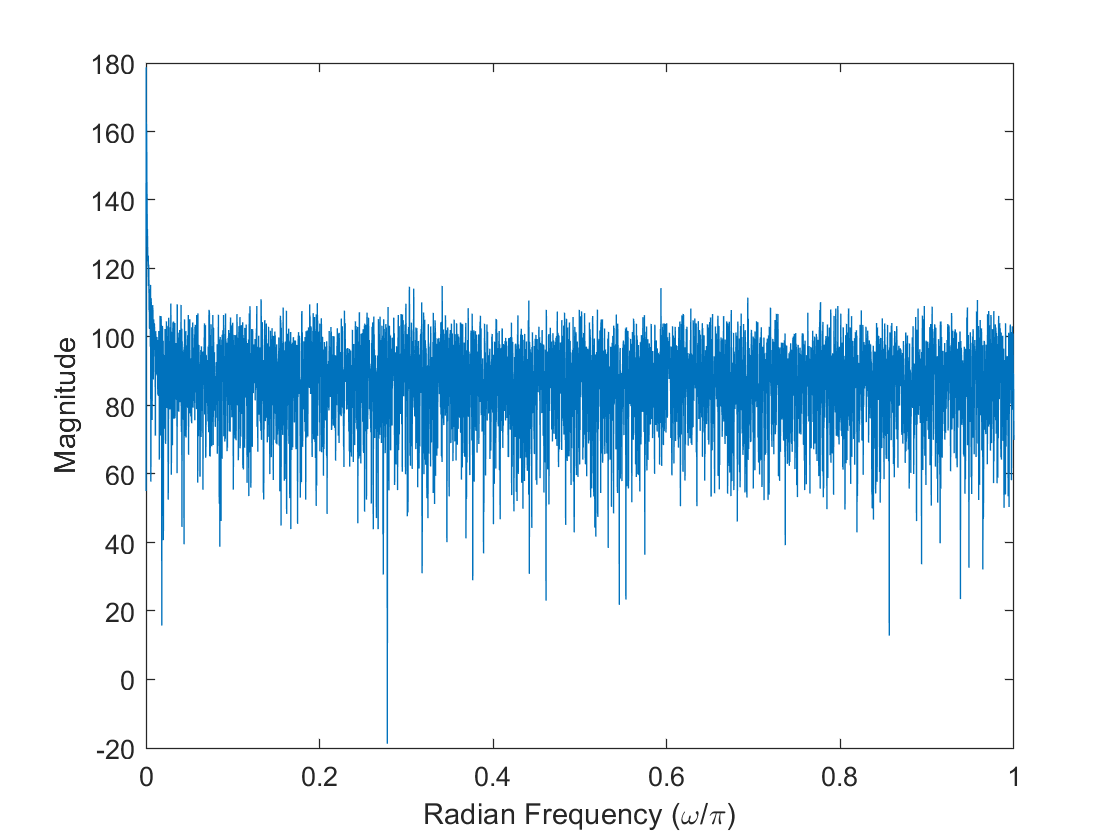

plot(omega,20*log(abs(X)))
xlabel 'Radian Frequency (\omega/\pi)', ylabel 'Magnitude'

Create a low pass filter

indeces = find(abs(X) > 2000)

indeces =      2     4     5


frequencies = omega(indeces)

frequencies = 	1.0e+-3 *

    0.2000    0.6001    0.8001


wp = omega(indeces(2))

wp = 6.0006e-04

ws = omega(indeces(3))

ws = 8.0008e-04

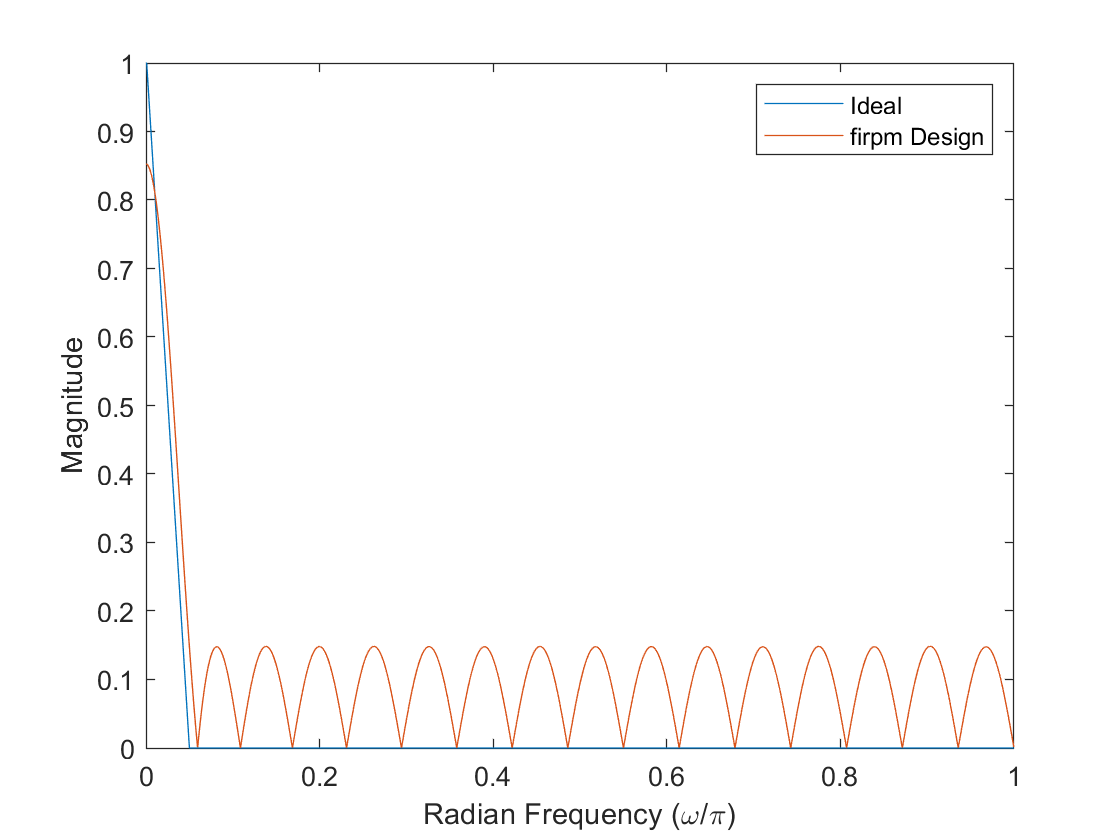


f = [0 wp (wp + ws)/2 ws 0.05 1];
a = [1 1 1 1 0 0];
b = firpm(31,f,a);

[h,w] = freqz(b,1,length(omega));
plot(f,a,w/pi,abs(h))
legend('Ideal','firpm Design')
xlabel 'Radian Frequency (\omega/\pi)', ylabel 'Magnitude'

Apply the low pass filter and see its result in the time and frequency domain

Y = (h').*X

Y = 	1.0e+03 *

   0.0134 + 0.0000i   6.4859 + 0.5113i   0.1678 - 1.0278i   1.7440 + 2.2426i  -0.7129 - 2.2031i  -0.2927 - 1.1895i  -0.1599 - 0.9521i  -0.0895 - 0.5836i  -0.0395 - 0.6063i  -0.0700 - 0.5192i  -0.0841 - 0.3702i  -0.0889 - 0.3985i  -0.0246 - 0.3530i   0.0433 - 0.4118i   0.1101 - 0.2416i   0.0356 - 0.3624i   0.1010 - 0.3163i   0.0322 - 0.2573i   0.0600 - 0.1766i   0.0584 - 0.2147i   0.0428 - 0.1348i  -0.0165 - 0.2366i   0.0549 - 0.1962i   0.1420 - 0.2097i   0.0171 - 0.2159i  -0.0249 - 0.1056i   0.0929 - 0.2506i   0.0769 - 0.0644i  -0.0022 - 0.0149i  -0.0426 - 0.1437i   0.0985 - 0.1954i   0.0680 - 0.1605i   0.0860 - 0.1648i  -0.0435 - 0.0308i   0.1274 - 0.0763i  -0.0225 - 0.0291i   0.0619 - 0.0793i  -0.0948 - 0.0999i   0.0683 - 0.1838i  -0.0801 - 0.1702i  -0.0744 - 0.1588i   0.0353 - 0.0701i  -0.0312 - 0.0578i   0.0347 - 0.0740i   0.0288 - 0.1548i   0.1090 - 0.0289i  -0.0226 - 0.1056i  -0.0186 - 0.1112i   0.0912 - 0.1163i   0.1171 - 0.0774i


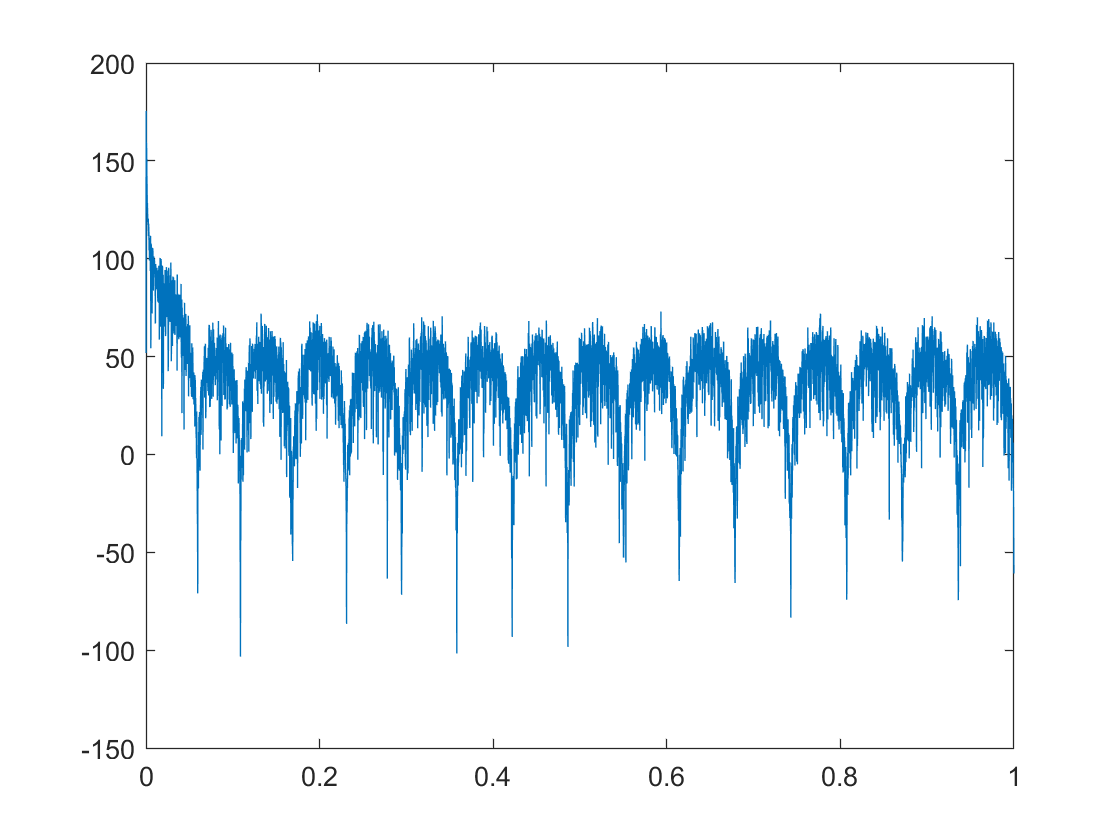

plot(omega, 20*log(abs(Y)))